# Single Sine Excitation of a Nonlinear Activation Unit: Arbitrary Gain Signals

Mauro J. Sanchirico III

## Setup

clc; clear; close all;

## Problem

A nonlinear activation unit with input gain $\gamma \text{\,}$ is defined:


$$\varphi \left(v\right)=tanh\left(\gamma \text{\,}v\right)$$


For input signal $v=sin\left(\omega t+\phi \text{\,}\right)$ we wish to know the Fourier Series of the output signal $y=\varphi \left(v\right)$

That is we want to know the Fourier Series of:


$$y\left(t\right)=tanh\left(\gamma \text{\,}sin\left(\omega t+\phi \text{\,}\right)\right)$$


When the input gain is restricted to $|\gamma |<\frac{\pi }{2}$, the following expression can be derived via straightforward Taylor series expansion, the power reduction formula for trigonometric polynomials, and series manipulations:


$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(-1\right)}^{2m-n-1} 4\left(2^{2m} -1\right){{\gamma \text{\,}}^{2m-1} C}_{m-n}^{2m-1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n-1\right)x\right)$$


Now we desire an expression for the Fourier Series of $y\left(t\right)$ for all $\gamma >0$.

## Classic Simplifications using Symmetry

First note that the function $y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)$ is odd:

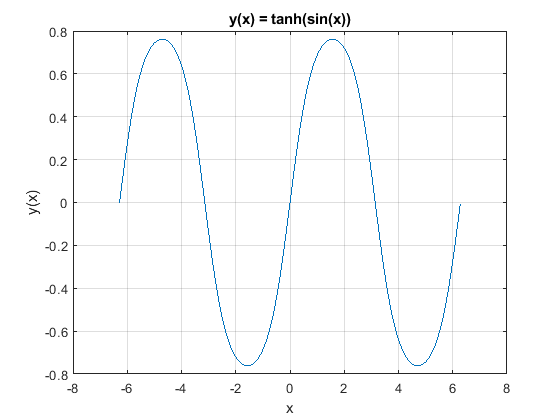

x = -2*pi:0.01:2*pi; y = tanh(sin(x));
figure; plot(x,y); xlabel('x'); ylabel('y(x)'); grid on; title('y(x) = tanh(sin(x))');

Now note the definition of the Fourier Series for a $2\pi$ periodic function:


$$y\left(x\right)=\frac{1}{2}a_0 +\sum_{n=1}^{\infty } a_n cos\left(n\text{\,}x\right)+\sum_{n=1}^{\infty } b_n sin\left(n\text{\,}x\right)$$


Where:


$$a_0 =\frac{1}{\pi \text{\,}}\int_{-\pi \text{\,}}^{\pi \text{\,}} y\left(x\right)dx,{\text{\,}\text{\,}a}_n =\frac{1}{\pi \text{\,}}\int_{-\pi \text{\,}}^{\pi \text{\,}} y\left(x\right)cos\left(nx\right)dx,\text{\,\,}b_n =\frac{1}{\pi \text{\,}}\int_{-\pi \text{\,}}^{\pi \text{\,}} y\left(x\right)sin\left(n\text{\,}x\right)dx$$


Now note $p_a \left(x\right)=tanh\left(sin\left(x\right)\right)cos\left(n\text{\,}x\right)$ is a product of an odd and an even function, and is therefore odd.  Likewise, $p_b \left(x\right)=\text{tanh}\left(\sin \left(x\right)\right)sin\left(n\text{\,}x\right)$ is a product of an odd function with another odd function, and is therefore even.

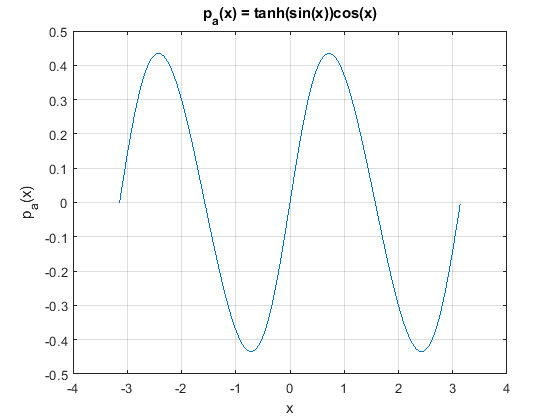

x = -pi:0.01:pi; pa = tanh(sin(x)).*cos(x); pb = tanh(sin(x)).*sin(x);
figure; plot(x,pa); xlabel('x'); ylabel('p_a(x)'); grid on; title('p_a(x) = tanh(sin(x))cos(x)');

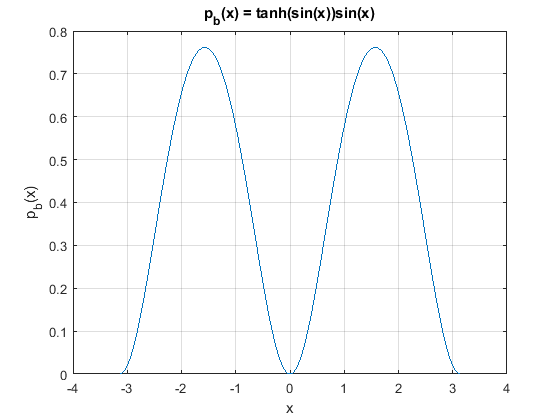

figure; plot(x,pb); xlabel('x'); ylabel('p_b(x)'); grid on; title('p_b(x) = tanh(sin(x))sin(x)');

The above plots make the following classic Fourier Series identities for odd $y\left(x\right)$ obvious:


$$a_0 =\frac{1}{\pi \text{\,}}\int_{-\pi }^{\pi } y\left(x\right)dx=0$$



$$a_n =\frac{1}{\pi \text{\,}}\int_{-\pi }^{\pi } y\left(x\right)cos\left(n\text{\,}x\right)\text{dx}=0$$



$$b_n =\frac{1}{\pi \text{\,}}\int_{-\pi }^{\pi } y\left(x\right)sin\left(n\text{\,}x\right)\text{dx}=\text{\,}\frac{2}{\pi \text{\,}}\int_0^{\pi } y\left(x\right)sin\left(n\text{\,}x\right)\text{dx}$$


Thus we can write an initial expression for the Fourier Series of $y\left(x\right)$:


$$y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(n\text{\,}x\right)\text{dx}\right\rbrace \sin \left(n\text{\,}x\right)$$


Additionally, because the hyperbolic tangent is an odd nonlinear function, we know that all the even components of the Fourier Series will be zero:


$$y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}\right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

***Theorem 1:***


$$y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}\right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Therefore determining an explicit expression for the integral $\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}$ will yeild the coefficients of the series.

We can test theorem 1 algorithmically by using numerical integration.  We see that for 20 Fourier Series terms, the harmonic approximation is very close to the truth, even for $\gamma >\frac{\pi }{2}$.

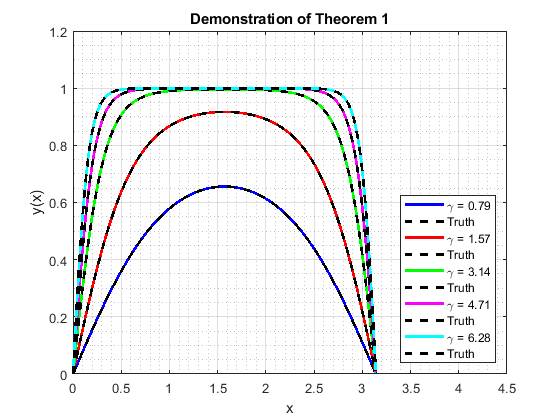

n_max = 20;
TestTheorem1(n_max);

## Expanding the Hyperbolic Tangent as an Exponential Sum

Now we need to evaluate:


$$\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}=\int_0^{\pi \text{\,}} I_1 \left(x\right)\text{dx}$$


We can start with rule 1.232.1 on page 27 (page 76 in the PDF version) of Gradsteyn and Rhyzik:


$$tanh\left(v\right)=1+2\sum_{m=1}^{\infty } {\left(-1\right)}^m e^{-2\text{\,}m\text{\,}v} \text{\,\,\,\,}\forall \text{\,}v>0$$


Giving:


$$I_1 \left(x\right)=\text{\,}\left(1+2\sum_{m=1}^{\infty } {\left(-1\right)}^m e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \right)\sin \left(\left(2n-1\right)\text{\,}x\right)$$


Therefore we have:


$$\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}=\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}+\int_0^{\pi \text{\,}} \left\lbrace 2\text{\,}\sin \left(\left(2n-1\right)\text{\,}x\right)\sum_{m=1}^{\infty } {\left(-1\right)}^m e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \right\rbrace \text{dx}$$


Evaluating the first integral and rearranging the second:


$$\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}=\frac{-\cos \left(\pi \left(2n-1\right)\right)+1}{2n-1}+\sum_{m=1}^{\infty } \left\lbrace {2\left(-1\right)}^m \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}\right\rbrace \text{\,}$$


Simplifying the cosine expression:


$$\frac{-\cos \left(\pi \left(2n-1\right)\right)+1}{2n-1}=\frac{2}{2n-1}$$



$$\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}=\frac{2}{2n-1}+\sum_{m=1}^{\infty } \left\lbrace {2\left(-1\right)}^m \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}\right\rbrace$$


Substituting the new expression for $\int_0^{\pi \text{\,}} \text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)\sin \left(\left(2n-1\right)\text{\,}x\right)\text{dx}$ into Theorem 1 gives Theorem 2:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

***Theorem 2:***


$$y\left(x\right)=\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \left\lbrace {2\left(-1\right)}^m \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}\right\rbrace \right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

We can test Theorem 2 algorithmically using numerical integration:

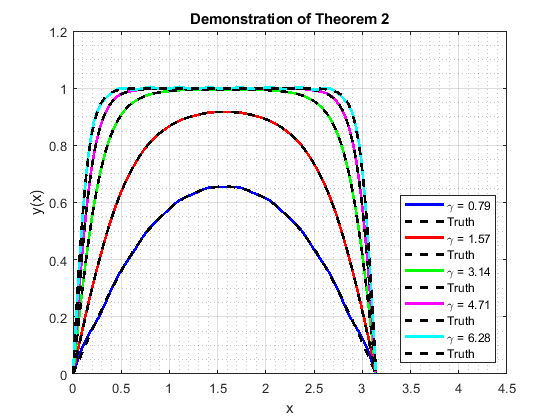

n_max = 10;
m_max = 50;
TestTheorem2(n_max, m_max);

## Evaluating the Reduced Integral

Now we have reduced evaluating the above expression to evaluating the reduced integral:


$$\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}=\int_0^{\pi \text{\,}} I_2 \left(x\right)\text{\,}\text{dx}$$


We start by taking the Taylor Series for $e^{-2\text{\,}m\text{\,}\gamma \text{\,}sin\left(x\right)\text{\,}}$ using:


$$e^{-2\text{\,}m\text{\,}v} =\text{\,}\sum_{l=0}^{\infty \text{\,}} \frac{\left(-2\text{\,}m\text{\,}v{\left.\right)}^l \right.}{l!}$$


Then the integrand is:


$$I_2 \left(x\right)=\sin \left(\left(2n-1\right)\text{\,}x\right)\sum_{l=0}^{\infty \text{\,}} \frac{{\left(-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\right)}^l }{l!}$$


Giving:


$$\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}=\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\sum_{l=0}^{\infty \text{\,}} \frac{{\left(-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\right)}^l }{l!}\text{dx}$$


Moving the summation symbol outside the integral:


$$\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}=\sum_{l=0}^{\infty \text{\,}} \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\frac{{\left(-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\right)}^l }{l!}\text{\,}\text{dx}$$


Distributing the exponent:


$$\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}=\sum_{l=0}^{\infty \text{\,}} \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\frac{\left(-2\text{\,}m\text{\,}\gamma {\left.\right)}^l \sin^l \left(x\right)\right.}{l!}\text{\,}\text{dx}$$


Moving all terms that are constant with respect to $x$ outside the integral:


$$\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)e^{-2\text{\,}m\text{\,}\gamma \text{\,}\sin \left(x\right)\text{\,}} \text{dx}=\sum_{l=0}^{\infty \text{\,}} \frac{{\left(-2\text{\,}m\text{\,}\gamma \right)}^l }{l!}\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)x\right)\sin^l \left(x\right)\text{dx}$$


Substituting back into Theorem 2:


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \left\lbrace {2\left(-1\right)}^m \left\lbrace \sum_{l=0}^{\infty \text{\,}} \frac{{\left(-2\text{\,}m\text{\,}\gamma \right)}^l }{l!}\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\sin^l \left(x\right)\text{dx}\right\rbrace \right\rbrace \right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


Rearranging the summations:


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \text{\,}} \frac{{2\left(-1\right)}^m {\left(-2\text{\,}m\text{\,}\gamma \right)}^l }{l!}\int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\sin^l \left(x\right)\text{dx}\right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


Cleaning up the indicies inside the summation over $l$ and $m$:


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \text{\,}} \frac{{\left(-1\right)}^{m+l} {2^{l+1} m^l } }{l!}\gamma^l \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\sin^l \left(x\right)\text{dx}\right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

***Theorem 3:***


$$\text{tanh}\left(\gamma \text{\,}\sin \left(x\right)\right)=\frac{2}{\pi \text{\,}}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \text{\,}} \frac{{\left(-1\right)}^{m+l} {2^{l+1} m^l } }{l!}\gamma^l \int_0^{\pi \text{\,}} \sin \left(\left(2n-1\right)\text{\,}x\right)\sin^l \left(x\right)\text{dx}\right\rbrace \sin \left(\left(2n-1\right)\text{\,}x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Theorem 3 is demonstrated below.  Due to numerical errors, it becomes very computationally expensive to approximate the series accurately for large gains.  However, convergence for gains larger than $\frac{\pi }{2}$ is still shown.  For L > 170, factorial(l) is exceeds machine precision and the approximation breaks down.  This expression has been verified for L = 200 in a sepparate script using variable precision arithmetic.

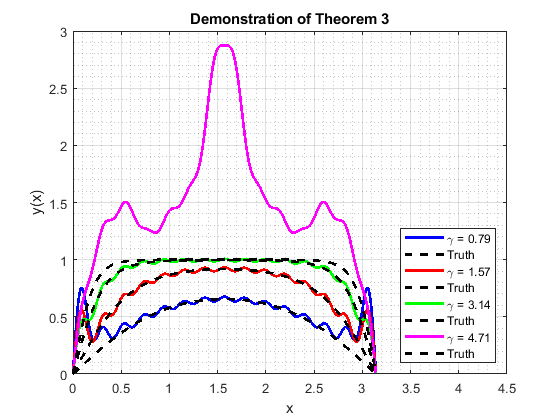

n_max = 15;   % Number of harmonics
m_max = 4;   % Number of exponentials
l_max = 150; % Number of Taylor series terms
TestTheorem3(n_max, m_max, l_max);

## Algorithms

% @breif Function for testing theorem 1 using numerical integration
% @details Numerically computes the Fourier Series of tanh(g*sin(x)) for
% several values of g.
% @param[in] n_max - Truncation of the Fourier Series

function TestTheorem1(n_max)
    x = 0:0.01:pi;
    gamma_list = [pi/4 pi/2 pi   3*pi/2 2*pi];
    colors     = ['b', 'r', 'g', 'm',   'c'];
    legend_strs = {};
    figure;
    for gamma_idx = 1:length(gamma_list)
        sum = 0;
        for n = 1:n_max
            integrand = tanh(gamma_list(gamma_idx)*sin(x)).*sin((2*n-1)*x);
            integral = trapz(x, integrand);
            sum = sum + integral*sin((2*n-1)*x);
        end
        y_approx = 2/pi*sum;
        y_truth = tanh(gamma_list(gamma_idx)*sin(x));
        plot(x, y_approx, '-', 'color', colors(gamma_idx), 'linewidth', 2);
        hold on;
        plot(x, y_truth, 'k--', 'linewidth', 2);
        legend_str = sprintf('\\gamma = %0.2f', gamma_list(gamma_idx));
        legend_strs{end+1} = legend_str;
        legend_strs{end+1} = 'Truth';
    end
    legend(legend_strs, 'location', 'southeast');
    grid on;
    grid minor;
    xlabel('x');
    ylabel('y(x)');
    title('Demonstration of Theorem 1');
    xlim([0 4.5]);
end

% @breif Function for testing theorem 2 using numerical integration
% @details Numerically computes the Fourier Series of tanh(g*sin(x)) for
% several values of g.
% @param[in] n_max - Truncation of the Fourier Series
% @param[in] m_max - Truncation of hyperbolic tangent's Taylor Series
function TestTheorem2(n_max, m_max)
    x = 0:0.01:pi;
    gamma_list = [pi/4 pi/2 pi   3*pi/2 2*pi];
    colors     = ['b', 'r', 'g', 'm',   'c'];
    legend_strs = {};
    figure;
    for gamma_idx = 1:length(gamma_list)
        outer_sum = 0;
        for n = 1:n_max  
            inner_sum = 0;
            for m = 1:m_max
                integrand = sin((2*n-1)*x).*exp(-2*m*gamma_list(gamma_idx)*sin(x));
                integral = trapz(x, integrand);
                inner_sum = inner_sum + 2*(-1)^m*integral;
            end
            outer_sum = outer_sum + (  2/(2*n-1) + inner_sum  )*sin((2*n-1)*x);
        end
        y_approx = 2/pi*outer_sum;
        y_truth = tanh(gamma_list(gamma_idx)*sin(x));
        plot(x, y_approx, '-', 'color', colors(gamma_idx), 'linewidth', 2);
        hold on;
        plot(x, y_truth, 'k--', 'linewidth', 2);
        legend_str = sprintf('\\gamma = %0.2f', gamma_list(gamma_idx));
        legend_strs{end+1} = legend_str;
        legend_strs{end+1} = 'Truth';
    end
    legend(legend_strs, 'location', 'southeast');
    grid on;
    grid minor;
    xlabel('x');
    ylabel('y(x)');
    title('Demonstration of Theorem 2');
    xlim([0 4.5]);
end

% @breif Function for testing theorem 3 using numerical integration
% @details Numerically computes the Fourier Series of tanh(g*sin(x)) for
% several values of g.
% @param[in] n_max - Truncation of the Fourier Series
% @param[in] m_max - Truncation of hyperbolic tangent's Taylor Series
% @param[in] l_max - Truncation of exponential function's Taylor Series
function TestTheorem3(n_max, m_max, l_max)
    x = 0:0.01:pi;
    gamma_list = [pi/4 pi/2 pi 3*pi/2];
    colors     = ['b'  'r' 'g' 'm'];
    legend_strs = {};
    figure;
    for gamma_idx = 1:length(gamma_list)
        n_sum = 0;
        for n = 1:n_max  
            m_sum = 0;
            for m = 1:m_max
                l_sum = 0;
                for l = 0:l_max
                    gamma_power = gamma_list(gamma_idx)^(l);
                    q = (-1)^(m+l)*(2)^(l+1)*m^l/factorial(l);
                    integrand = sin((2*n-1)*x).*(sin(x).^(l));
                    integral = trapz(x, integrand);
                    l_sum = l_sum + q*integral*gamma_power;
                end
                m_sum = m_sum + l_sum;
            end
            n_sum = n_sum + (2/(2*n-1) + m_sum)*sin((2*n-1)*x);
        end
        y_approx = 2/pi*n_sum;
        y_truth = tanh(gamma_list(gamma_idx)*sin(x));
        plot(x, y_approx, '-', 'color', colors(gamma_idx), 'linewidth', 2);
        hold on;
        plot(x, y_truth, 'k--', 'linewidth', 2);
        legend_str = sprintf('\\gamma = %0.2f', gamma_list(gamma_idx));
        legend_strs{end+1} = legend_str;
        legend_strs{end+1} = 'Truth';
    end
    legend(legend_strs, 'location', 'southeast');
    grid on;
    grid minor;
    xlabel('x');
    ylabel('y(x)');
    title('Demonstration of Theorem 3');
    xlim([0 4.5]);
end